# Project 1 MA  493 

Authored: Sarah Bird , Nicholas Gawron , Jamie Loring , Andrea Stancescu 

Date: March 4, 2022

## Part I

Implement k-means clustering with random initialization by sampling components using a uniform distribution for each component on the interval [−1.2, 1.2] and using the k++ initialization 

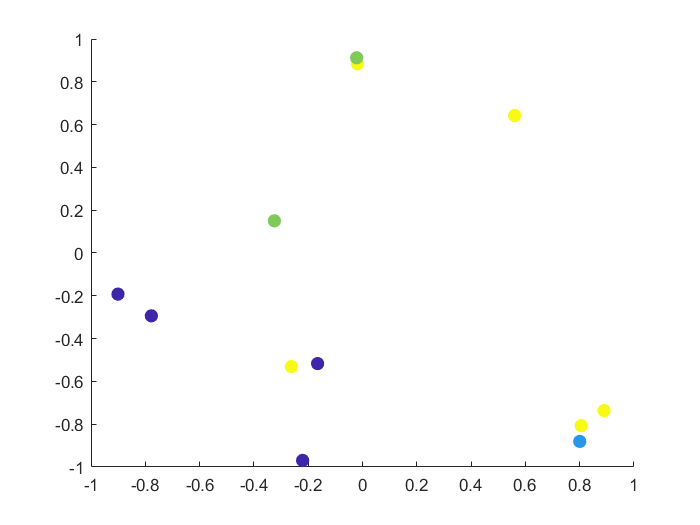

% Clear the workspace and close all figure windows
clear all
close all
% 
% Set the number of data vectors (n) and the dimension of the data space (m)
n=12; % Example 1
%n=100; %random data 
m=2;

% Set the number of clusters (k)
k=5;

% Initialize the data using random data
XData = zeros(n,m);
XData = -1*ones(n,m) + 2*rand(n,m);

%  Assign each data vector, randomly to one of the k clusters
IndexSet = randi(k,n,1);

% Plot the data
scatter(XData(:,1),XData(:,2),64,IndexSet,'filled');
hold on


% Create data structures to store the weight vectors for cluster (c), and the 
% weight vectors from the previous iteration (cPrev)
c = zeros(k,m);
cPrev = zeros(k,m);

% Randomly initialize the weight vectors so that each component is sampled from 
% the interval [-1,1]
c(1,:) = -1.2 + 2*rand(1,m)

c =    -0.4630    0.0512
         0         0
         0         0
         0         0
         0         0


c(2,:) = max(norm(c(1,:), XData, 2))

Error using norm
Too many input arguments.

c(3,:) = max(norm(c(2,:), XData, 2))
c(4,:) = max(norm(c(3,:), XData, 2))
c(5,:) = max(norm(c(4,:), XData, 2))

% Plot the initial weight vectors
scatter(c(:,1),c(:,2),200,linspace(1,k,k))
hold off
pause

%% The Alternating Minimization Scheme
doneFlag=0;

% Keep alternating updates to weight vectors and cluster assignments until weight 
% vectors no longer change their locations

while (~doneFlag)

    % Update the weight vectors in each cluster via the centroid formula
    for i=1:k 

        % Find the indices for all data vectors currently in cluster i
        ClusterIndices = find(IndexSet==i);

        % Find the number of data vectors currently in cluster i
        NumVecsInCluster = size(ClusterIndices,1);

        % Create a data structure to store weight vector for the current
        % cluster
        c(i,:)=0; 

        % Update cluster vector using the centroid formula
        for j=1:NumVecsInCluster
            for l=1:m
                c(i,l) = c(i,l) + XData(ClusterIndices(j,1),l)/NumVecsInCluster;
            end
        end

    end

    % Plot the updated weight vectors for each cluster
    scatter(XData(:,1),XData(:,2),64,IndexSet,'filled')
    hold on
    scatter(c(:,1),c(:,2),200,linspace(1,k,k))
    pause
    
    % Now reassign all data vectors to the closest weight vector (cluster)

    % Create a data structure to store closest weight vector for each data
    % point
    closestCluster=zeros(n,1);

    % Reassign each data vector to the new, closest cluster
    for d=1:n

        % Store the coordinates of the current data vector
        xD = XData(d,:);

        % Set the minimum distance tracker to be a very large number
        sqDistMin=1e16;

        % Find the closest weight vector (cluster) to the current data
        % vector
        for i=1:k
            sqDist = norm(c(i,:)-xD,2);

            % If the distance is less than the current min, assign the
            % current data vector to this cluster
            if sqDist<sqDistMin
                closestCluster(d)=i;
                sqDistMin=sqDist;
            end

        end
    end

    % Update the assignments of the data vectors to their new clusters
    IndexSet = closestCluster;
    
    % Plot the data and the updated weight vectors
    hold off
    scatter(XData(:,1),XData(:,2),64,IndexSet,'filled')
    hold on
    scatter(c(:,1),c(:,2),200,linspace(1,k,k))
    hold off
    pause
    
    % Terminate the alternating scheme if the weight vectors are unaltered
    % relative to the previous iteration
    if c==cPrev
        doneFlag=1;
    else
        cPrev=c;
    end
end
